clear all
sympref('FloatingPointOutput', false)

## Problem 2

### Part A

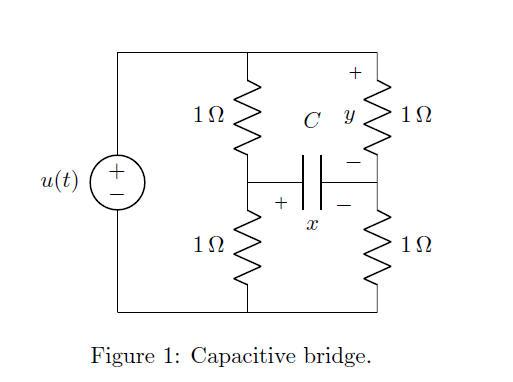

syms i_1 i_2 i_3 u x x_dot y C
%Loop 1 equation
l1eqn = i_1 + i_2 == u

$$l1eqn = i_{1}+i_{2}=u$$


%Node 1 equation
n1eqn = i_1 - i_2 == C*x_dot

$$n1eqn = i_{1}-i_{2}=C\,\dot{x}$$


%Loop 2 equation
l2eqn = -i_1 + y - x == 0

$$l2eqn = -x+y-i_{1}=0$$


%Node 2 equation
n2eqn = -y + i_3 == C*x_dot

$$n2eqn = -y+i_{3}=C\,\dot{x}$$


%Loop 2 equation
l3eqn = -i_2 + x + i_3 == 0

$$l3eqn = x-i_{2}+i_{3}=0$$


eqns = [l1eqn;n1eqn;l2eqn;n2eqn;l3eqn]

$$eqns = \left[\begin{array}{c} i_{1}+i_{2}=u\\ i_{1}-i_{2}=C\,\dot{x}\\ -x+y-i_{1}=0\\ -y+i_{3}=C\,\dot{x}\\ x-i_{2}+i_{3}=0 \end{array}\right]$$

state_eqn = 0 == eliminate(eqns, [i_1 i_2 i_3 y]);
state_eqn = isolate(state_eqn, x_dot)

$$state\_eqn = \dot{x}=-\frac{x}{C}$$

output_eqn = 0 == eliminate(eqns, [i_1 i_2 i_3 x_dot])

$$output\_eqn = 0=x-2\,y+u$$

output_eqn = isolate(output_eqn, y)

$$output\_eqn = y=\frac{x}{2}+\frac{u}{2}$$

### Part B

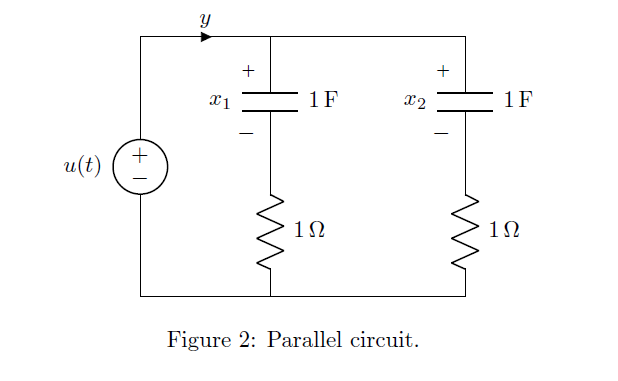

syms x_1 x_2 x_dot_1 x_dot_2 

%Loop 1 equation
l1eqn = x_1 + i_1 - u == 0

$$l1eqn = x_{1}-u+i_{1}=0$$


%Loop 2 equation
l2eqn = x_2 + i_2 - u == 0

$$l2eqn = x_{2}-u+i_{2}=0$$


%Node 1 equation
n1eqn = y == x_dot_1 + x_dot_2

$$n1eqn = y={\dot{x}}_{1}+{\dot{x}}_{2}$$


%Node 2 equation
n2eqn = i_1 == x_dot_1

$$n2eqn = i_{1}={\dot{x}}_{1}$$


%Node 3 equation
n3eqn = i_2 == x_dot_2

$$n3eqn = i_{2}={\dot{x}}_{2}$$


eqns = [l1eqn;l2eqn;n1eqn;n2eqn;n3eqn]

$$eqns = \left[\begin{array}{c} x_{1}-u+i_{1}=0\\ x_{2}-u+i_{2}=0\\ y={\dot{x}}_{1}+{\dot{x}}_{2}\\ i_{1}={\dot{x}}_{1}\\ i_{2}={\dot{x}}_{2} \end{array}\right]$$

solved_state_eqns = eliminate(eqns, [i_1 i_2 y])

$$solved\_state\_eqns = \left[-x_{2}-{\dot{x}}_{2}+u,x_{1}-x_{2}+{\dot{x}}_{1}-{\dot{x}}_{2}\right]$$

solved_state_eqns = [0;0] == [solved_state_eqns(1);solved_state_eqns(2)];
solved_state_eqns = [solved_state_eqns(1)-solved_state_eqns(2);solved_state_eqns(1)];
solved_state_eqns = [isolate(solved_state_eqns(1), x_dot_1);isolate(solved_state_eqns(2), x_dot_2)]

$$solved\_state\_eqns = \left[\begin{array}{c} {\dot{x}}_{1}=-x_{1}+u\\ {\dot{x}}_{2}=-x_{2}+u \end{array}\right]$$

solved_output_eqn = 0 == eliminate(eqns, [i_1 i_2 x_dot_1 x_dot_2]);
solved_output_eqn = isolate(solved_output_eqn, y)

$$solved\_output\_eqn = y=-x_{1}-x_{2}+2\,u$$

## Problem 3 

### Part A

State space model of spring mass system:

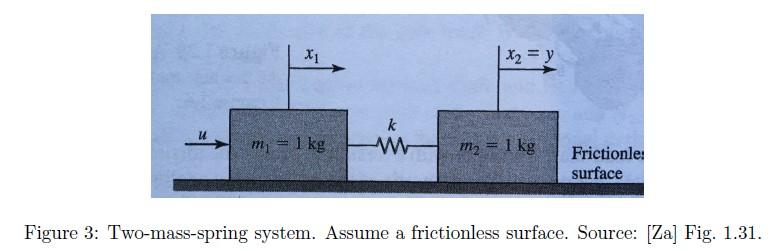

Here, the state space model is $\dot{x} = Ax + Bu$ where $x = [~x_1~x_2~\dot{x}_1~\dot{x}_2~]$

m1 = 1;
m2 = 1;
k = 1;

A = [0      0   1  0
        0      0   0  1
      -k/m1  k/m1  0  0
       k/m2 -k/m2  0  0];

B = [ 0
      0 
     1/m1
      0 ];

C = [ 0 1 0 0];

D = 0;

sys = ss(A,B,C,D);

#### Controllability Gramian $W_c$


$$W_c(t) = \int_{0}^{t} e^{A\tau}BB^Te^{A^T\tau} \,d\tau$$


syms Tau t n

Symbolic Integrand for $W_c$

Wc_integrand = expm(A*Tau)*(B*B.')*expm(A.'*Tau);

Symbolically Integrate (too large to display)

Wc(t) = int(Wc_integrand,Tau, 0, t);

#### Evaluate $W_c$ at the time values $t_1 = 10 , ~t_2 = 20, ~ and~t_3 = 100$ and determine wether or not $W_c(t_1), W_c(t_2), W_c(t_3)$ are convergent.

Via a proof shown in the hand calculations, any real diagonalizable matrix is convergent if and only if all of its eigenvalues are less than 1. The controllability grammians of this system are all real and diagonalizable and are shown to each have at least one eigenvalue greater than 1. 

t1 = 10;
t2 = 20;
t3 = 100;
Wc1 = double(Wc(t1))

Wc1 =    84.1477   82.7081   14.3302   10.9210
   82.7081   83.7694   13.9540   10.7948
   14.3302   13.9540    4.1031    1.2504
   10.9210   10.7948    1.2504    3.3960


Wc2 = double(Wc(t2))

Wc2 =   672.9142  665.4171   49.9649   50.5351
  665.4171  662.9182   49.4649   50.0351
   49.9649   49.4649    7.4974    2.4991
   50.5351   50.0351    2.4991    7.5044


Wc3 = double(Wc(t3))

Wc3 = 	1.0e+04 *

    8.3365    8.3327    0.1249    0.1251
    8.3327    8.3315    0.1249    0.1251
    0.1249    0.1249    0.0037    0.0012
    0.1251    0.1251    0.0012    0.0038


**t1 = 10 sec **

% V is the matrix of eigenvectors and D is a diagonal matrix of eigenvalues
[V1, Wc_bar_1] = eig(Wc1);
%Make sure they are ordered from largest to smallest
[eigvals1,ind1] = sort(diag(Wc_bar_1), 'descend');
disp(["Reordered Eigenvalue of Wc1 = " + eigvals1 "Index = " + ind1]);

    "Reordered Eigenvalue of Wc1 = 170.5095"     "Index = 4"
    "Reordered Eigenvalue of Wc1 = 2.458196"     "Index = 3"
    "Reordered Eigenvalue of Wc1 = 1.456741"     "Index = 2"
    "Reordered Eigenvalue of Wc1 = 0.9917897"    "Index = 1"



Wc_bar_s1 = Wc_bar_1(ind1,ind1)

Wc_bar_s1 =   170.5095         0         0         0
         0    2.4582         0         0
         0         0    1.4567         0
         0         0         0    0.9918


Since the matrix $\bar{W_c}_1$, which is in the eigenbasis of ${W_c}_1$, has at least one eigenvalue greater than 1, $$\lim_{n \to \infty} {{W_c}_1}^n~\neq~ \tilde{0}$ $. I.e. ${W_c}_1$ does not converge (see hand calculations for proof).

%Reordered Eigenvectors
Vs1 = V1(:,ind1) 

Vs1 =     0.7000    0.0540   -0.4444   -0.5565
    0.6981   -0.0605    0.5900    0.4011
    0.1195    0.6300   -0.4824    0.5967
    0.0917   -0.7723   -0.4708    0.4164


**t2 = 20 sec**

% V is the matrix of eigenvectors and D is a diagonal matrix of eigenvalues
[V2, Wc_bar_2] = eig(Wc2);
%Make sure they are ordered from largest to smallest
[eigvals2,ind2] = sort(diag(Wc_bar_2), 'descend');
disp(["Reordered Eigenvalue of Wc2 = " + eigvals2 "Index = " + ind2]);

    "Reordered Eigenvalue of Wc2 = 1340.8664"    "Index = 4"
    "Reordered Eigenvalue of Wc2 = 5.0021324"    "Index = 3"
    "Reordered Eigenvalue of Wc2 = 2.6068916"    "Index = 2"
    "Reordered Eigenvalue of Wc2 = 2.3587624"    "Index = 1"



Wc_bar_s2 = Wc_bar_2(ind2,ind2)

Wc_bar_s2 = 	1.0e+03 *

    1.3409         0         0         0
         0    0.0050         0         0
         0         0    0.0026         0
         0         0         0    0.0024


Since the matrix $\bar{W_c}_2$, which is in the eigenbasis of ${W_c}_2$, has at least one eigenvalue greater than 1, $$\lim_{n \to \infty} {{W_c}_2}^n~\neq~ \tilde{0}$ $. I.e. ${W_c}_2$ does not converge (see hand calculations for proof).

%Reordered Eigenvectors
Vs2 = V2(:,ind2)

Vs2 =     0.7078   -0.0006    0.4551    0.5403
    0.7025    0.0017   -0.5345   -0.4699
    0.0527   -0.7181    0.4948   -0.4866
    0.0533    0.6959    0.5122   -0.5005


**t3 = 100 sec**

% V is the matrix of eigenvectors and D is a diagonal matrix of eigenvalues
[V3, Wc_bar_3] = eig(Wc3);
%Make sure they are ordered from largest to smallest
[eigvals3,ind3] = sort(diag(Wc_bar_3), 'descend');
disp(["Reordered Eigenvalue of Wc3 = " + eigvals3 "Index = " + ind3]);

    "Reordered Eigenvalue of Wc3 = 166704.1732"    "Index = 4"
    "Reordered Eigenvalue of Wc3 = 25.00875972"    "Index = 3"
    "Reordered Eigenvalue of Wc3 = 12.61979239"    "Index = 2"
    "Reordered Eigenvalue of Wc3 = 12.36925083"    "Index = 1"



Wc_bar_s3 = Wc_bar_3(ind3,ind3)

Wc_bar_s3 = 	1.0e+05 *

    1.6670         0         0         0
         0    0.0003         0         0
         0         0    0.0001         0
         0         0         0    0.0001


Since the matrix $\bar{W_c}_3$, which is in the eigenbasis of ${W_c}_3$, has at least one eigenvalue greater than 1, $$\lim_{n \to \infty} {{W_c}_3}^n~\neq~ \tilde{0}$ $. I.e. ${W_c}_3$ does not converge (see hand calculations for proof).

%Reordered Eigenvectors
Vs3 = V3(:,ind3)

Vs3 =     0.7071    0.0000    0.4870   -0.5126
    0.7069   -0.0000   -0.5023    0.4979
    0.0106    0.7080    0.5045    0.4940
    0.0106   -0.7062    0.5059    0.4952


#### Which States Are Most Controllable?

The degree of controllability of any state in this system is determined, roughly, by how much of the eigenvector associated with the dominant eigenvalue lies in the direction of that state. Since for each of these controllibility Gramian matrices, there is one eigenvalue that is orders of magnitude larger than the others, this is a good criteria. 

**For **$t_1 = 10 s$, the dominant eigenvector is: 

Vs1(:,1)

ans =     0.7000
    0.6981
    0.1195
    0.0917


Which has the associated eigenvalue: 

disp(eigvals1(1))

  170.5095



The eigenvalue points largely in the directions of $x_1$ and $x_2$, but is slightly more in $x_1$ than it is in $x_2$. These states are the most controllable. 

**For **$t_2 = 20 s$, the dominant eigenvector is: 

Vs2(:,1)

ans =     0.7078
    0.7025
    0.0527
    0.0533


Which has the associated eigenvalue: 

disp(eigvals2(1))

   1.3409e+03



The eigenvalue points largely in the directions of $x_1$ and $x_2$, but is slightly more in $x_1$ than it is in $x_2$. These states are the most controllable. 

**For **$t_3 = 100 s$, the dominant eigenvector is: 

Vs3(:,1)

ans =     0.7071
    0.7069
    0.0106
    0.0106


Which has the associated eigenvalue: 

disp(eigvals3(1))

   1.6670e+05



The eigenvalue points largely in the directions of $x_1$ and $x_2$, but is slightly more in $x_1$ than it is in $x_2$. These states are the most controllable. 

The clear trend is that the position states tend to be much more controllable than the velocity states and $x_1$, where the input most direclty affects the mass, is slightly more controllable than $x_2$.

#### Observability Gramian $W_o$


$$W_o(t) = \int_{0}^{t} e^{A^T\tau}C^TCe^{A\tau} \,d\tau$$


Symbolic Integrand for $W_o$

Wo_integrand = expm(A'*Tau)*(C'*C)*expm(A*Tau);

Symbolically Integrate (too large to display)

Wo(t) = int(Wo_integrand,Tau, 0, t);

#### Evaluate $W_o$ at the time values $t_1 = 10 , ~t_2 = 20, ~ and~t_3 = 100$ and determine wether or not $W_o(t_1), W_o(t_2), W_o(t_3)$ are convergent.

Via a proof shown in the hand calculations, any real diagonalizable matrix is convergent if and only if all of its eigenvalues are less than 1. The observability grammians of this system are all real and diagonalizable and are shown to each have at least one eigenvalue greater than 1. 

Wo1 = double(Wo(t1))

Wo1 =     3.3960    1.2504   10.7948   10.9210
    1.2504    4.1031   13.9540   14.3302
   10.7948   13.9540   83.7694   82.7081
   10.9210   14.3302   82.7081   84.1477


Wo2 = double(Wo(t2))

Wo2 =     7.5044    2.4991   50.0351   50.5351
    2.4991    7.4974   49.4649   49.9649
   50.0351   49.4649  662.9182  665.4171
   50.5351   49.9649  665.4171  672.9142


Wo3 = double(Wo(t3))

Wo3 = 	1.0e+04 *

    0.0038    0.0012    0.1251    0.1251
    0.0012    0.0037    0.1249    0.1249
    0.1251    0.1249    8.3315    8.3327
    0.1251    0.1249    8.3327    8.3365


**t1 = 10 sec **

% V is the matrix of eigenvectors and D is a diagonal matrix of eigenvalues
[V1, Wo_bar_1] = eig(Wo1);
%Make sure they are ordered from largest to smallest
[eigvals1,ind1] = sort(diag(Wo_bar_1), 'descend');
disp(["Reordered Eigenvalue of Wo1 = " + eigvals1 "Index = " + ind1]);

    "Reordered Eigenvalue of Wo1 = 170.5095"     "Index = 4"
    "Reordered Eigenvalue of Wo1 = 2.458196"     "Index = 3"
    "Reordered Eigenvalue of Wo1 = 1.456741"     "Index = 2"
    "Reordered Eigenvalue of Wo1 = 0.9917897"    "Index = 1"



Wo_bar_s1 = Wo_bar_1(ind1,ind1)

Wo_bar_s1 =   170.5095         0         0         0
         0    2.4582         0         0
         0         0    1.4567         0
         0         0         0    0.9918


Since the matrix $\bar{W_o}_1$, which is in the eigenbasis of ${W_o}_1$, has at least one eigenvalue greater than 1, $$\lim_{n \to \infty} {{W_o}_1}^n~\neq~ \tilde{0}$ $. I.e. ${W_o}_1$ does not converge (see hand calculations for proof).

%Reordered Eigenvectors
Vs1 = V1(:,ind1) 

Vs1 =     0.0917    0.7723   -0.4708    0.4164
    0.1195   -0.6300   -0.4824    0.5967
    0.6981    0.0605    0.5900    0.4011
    0.7000   -0.0540   -0.4444   -0.5565


**t2 = 20 sec**

% V is the matrix of eigenvectors and D is a diagonal matrix of eigenvalues
[V2, Wo_bar_2] = eig(Wo2);
%Make sure they are ordered from largest to smallest
[eigvals2,ind2] = sort(diag(Wo_bar_2), 'descend');
disp(["Reordered Eigenvalue of Wo2 = " + eigvals2 "Index = " + ind2]);

    "Reordered Eigenvalue of Wo2 = 1340.8664"    "Index = 4"
    "Reordered Eigenvalue of Wo2 = 5.0021324"    "Index = 3"
    "Reordered Eigenvalue of Wo2 = 2.6068916"    "Index = 2"
    "Reordered Eigenvalue of Wo2 = 2.3587624"    "Index = 1"



Wo_bar_s2 = Wo_bar_2(ind2,ind2)

Wo_bar_s2 = 	1.0e+03 *

    1.3409         0         0         0
         0    0.0050         0         0
         0         0    0.0026         0
         0         0         0    0.0024


Since the matrix $\bar{W_o}_2$, which is in the eigenbasis of ${W_o}_2$, has at least one eigenvalue greater than 1, $$\lim_{n \to \infty} {{W_o}_2}^n~\neq~ \tilde{0}$ $. I.e. ${W_o}_2$ does not converge (see hand calculations for proof).

%Reordered Eigenvectors
Vs2 = V2(:,ind2)

Vs2 =     0.0533    0.6959   -0.5122    0.5005
    0.0527   -0.7181   -0.4948    0.4866
    0.7025    0.0017    0.5345    0.4699
    0.7078   -0.0006   -0.4551   -0.5403


**t3 = 100 sec**

% V is the matrix of eigenvectors and D is a diagonal matrix of eigenvalues
[V3, Wo_bar_3] = eig(Wo3);
%Make sure they are ordered from largest to smallest
[eigvals3,ind3] = sort(diag(Wo_bar_3), 'descend');
disp(["Reordered Eigenvalue of Wo3 = " + eigvals3 "Index = " + ind3]);

    "Reordered Eigenvalue of Wo3 = 166704.1732"    "Index = 4"
    "Reordered Eigenvalue of Wo3 = 25.00875972"    "Index = 3"
    "Reordered Eigenvalue of Wo3 = 12.61979239"    "Index = 2"
    "Reordered Eigenvalue of Wo3 = 12.36925083"    "Index = 1"



Wo_bar_s3 = Wo_bar_3(ind3,ind3)

Wo_bar_s3 = 	1.0e+05 *

    1.6670         0         0         0
         0    0.0003         0         0
         0         0    0.0001         0
         0         0         0    0.0001


Since the matrix $\bar{W_o}_3$, which is in the eigenbasis of ${W_o}_3$, has at least one eigenvalue greater than 1, $$\lim_{n \to \infty} {{W_o}_3}^n~\neq~ \tilde{0}$ $. I.e. ${W_o}_3$ does not converge (see hand calculations for proof).

%Reordered Eigenvectors
Vs3 = V3(:,ind3)

Vs3 =     0.0106    0.7062   -0.5059   -0.4952
    0.0106   -0.7080   -0.5045   -0.4940
    0.7069    0.0000    0.5023   -0.4979
    0.7071   -0.0000   -0.4870    0.5126


#### Which States Are Most Observable?

The degree of observability of any state in this system is determined, roughly, by how much of the eigenvector associated with the dominant eigenvalue lies in the direction of that state. Since for each of these observability Gramian matrices, there is one eigenvalue that is orders of magnitude larger than the others, this is a good criteria. 

**For **$t_1 = 10 s$, the dominant eigenvector is: 

Vs1(:,1)

ans =     0.0917
    0.1195
    0.6981
    0.7000


Which has the associated eigenvalue: 

disp(eigvals1(1))

  170.5095



The eigenvalue points largely in the directions of $\dot{x}_1$ and $\dot{x}_2$, but is slightly more in $\dot{x}_2$ than it is in $\dot{x}_1$. These states are the most observable. 

**For **$t_2 = 20 s$, the dominant eigenvector is: 

Vs2(:,1)

ans =     0.0533
    0.0527
    0.7025
    0.7078


Which has the associated eigenvalue: 

disp(eigvals2(1))

   1.3409e+03



The eigenvalue points largely in the directions of $\dot{x}_1$ and $\dot{x}_2$, but is slightly more in $\dot{x}_2$ than it is in $\dot{x}_1$. These states are the most observable. 

**For **$t_3 = 100 s$, the dominant eigenvector is: 

Vs3(:,1)

ans =     0.0106
    0.0106
    0.7069
    0.7071


Which has the associated eigenvalue: 

disp(eigvals3(1))

   1.6670e+05



The eigenvalue points largely in the directions of $\dot{x}_1$ and $\dot{x}_2$, but is slightly more in $\dot{x}_2$ than it is in $\dot{x}_1$. These states are the most observable. 

The clear trend is that the velocity states tend to be much more observable than the position states and $\dot{x}_2$, is slightly more observable than $\dot{x}_1$.

### Part B

### Part C


$$u(t) = -B^Te^{A^T(t_1-t)}W_c^{-1}(t_1)[e^{At}x_0-x_1]$$
